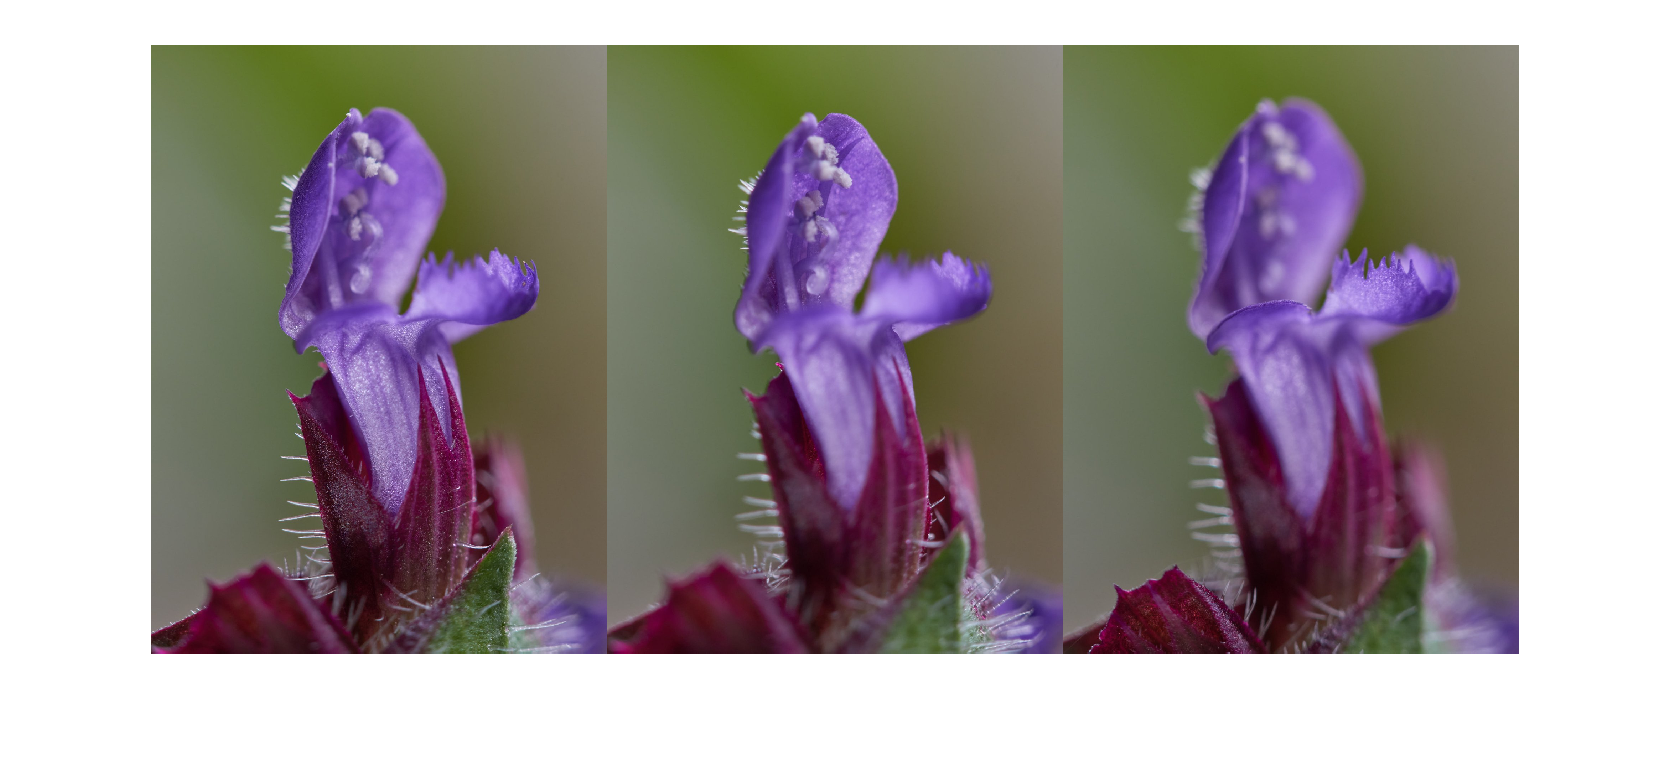

img1 = imread("img1.jpg");
img2 = imread("img2.jpg");
img3 = imread("img3.jpg");

montage({img1, img2, img3}, 'Size', [1 3])

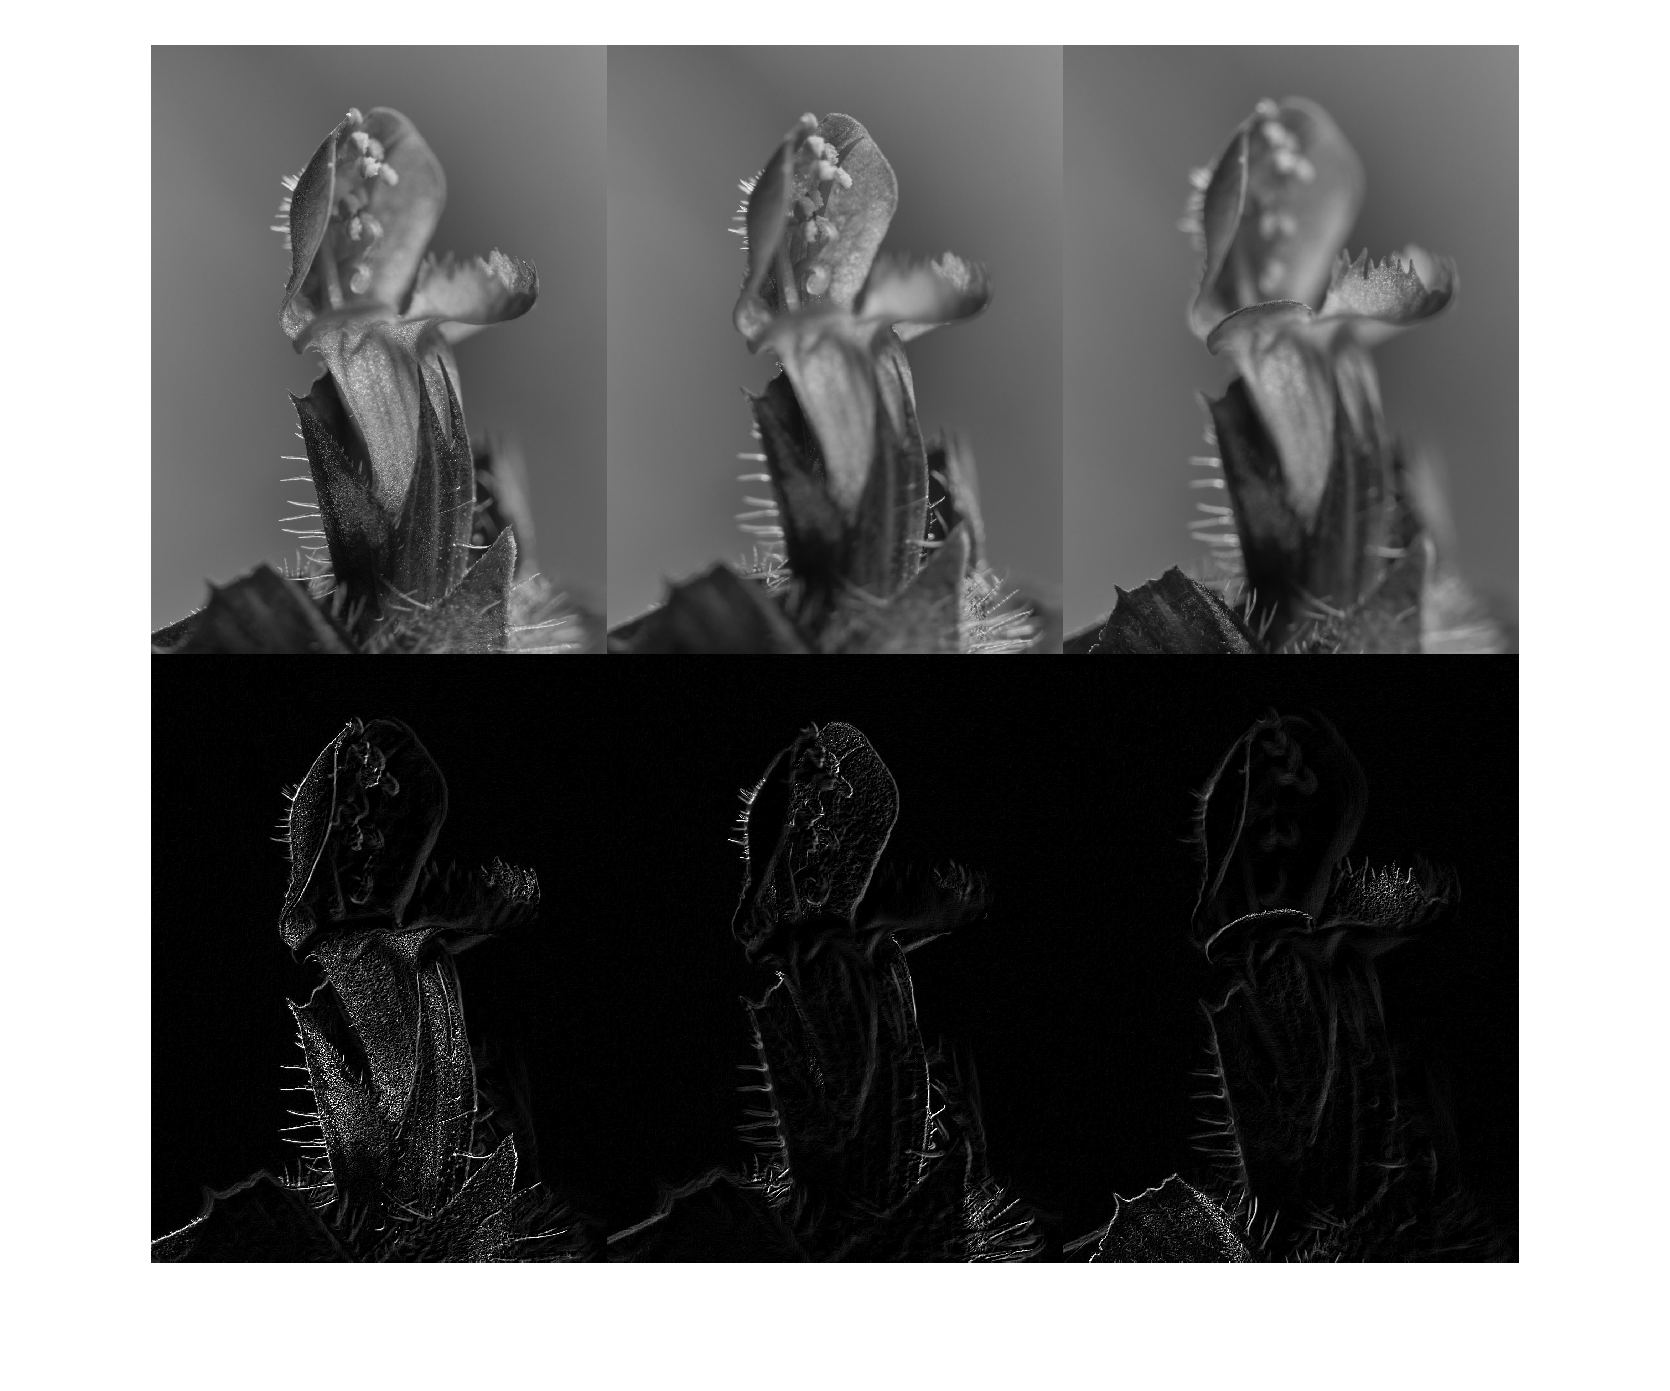


img1 = rgb2gray(img1);
img2 = rgb2gray(img2);
img3 = rgb2gray(img3);

fimg1 = filtre_der(img1);
fimg2 = filtre_der(img2);
fimg3 = filtre_der(img3);
montage({img1, img2, img3, fimg1, fimg2, fimg3}, 'Size', [2 3])


m1 = get_m(fimg1)

m1 = int32
10165749

m2 = get_m(fimg2)

m2 = int32
5035946

m3 = get_m(fimg3)

m3 = int32
4156288

function fimg = filtre_der(img)
h = fspecial('sobel');
Sx = imfilter(img, h);
Sy = imfilter(img, h');
fimg = imadd(Sx, Sy);

sup = sum(sum(fimg < 0));
inf = sum(sum(fimg > 255));
if sup > 0 || inf > 0
    error("Valores negativos o mayores a 255");
end
end

function m = get_m(img)
mida = size(img);
if mida(1) > mida(2)
   max_dist = mida(1) / 2;
else
   max_dist = mida(2) / 2;
end

x0 = mida(1) / 2;
y0 = mida(2) / 2;

m = 0;
for x1 = 1:mida(1)
    for y1 = 1:mida(2)
        dist = sqrt((x1 - x0)^2+(y1 - y0)^2);
        m = m + int32(img(x1, y1)) * (1 - dist/max_dist);
    end
end
end
